# FFT Exercise 3 signals 

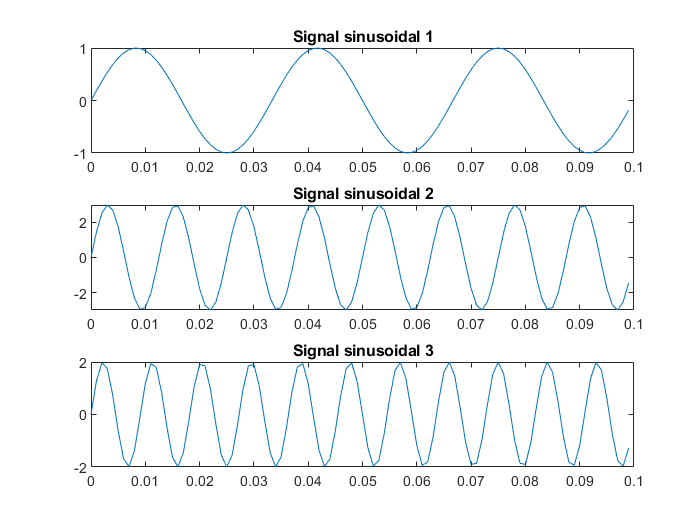

Fs = 1000;                    % Sampling frequency
T = 1/Fs;                     % Sampling period
L = 1500;                     % Length of signal
t = (0:L-1)*T;                % Time vector

x1 = sin(2*pi*30*t);          % First row wave
x2 = 3*sin(2*pi*80*t);         % Second row wave
x3 = 2*sin(2*pi*110*t);         % Third row wave
X = [x1; x2; x3];

for i = 1:3                     % Plot the 3 signals in a figure
    subplot(3,1,i)
    plot(t(1:100),X(i,1:100))
    title(['Signal sinusoidal ',num2str(i)])
end

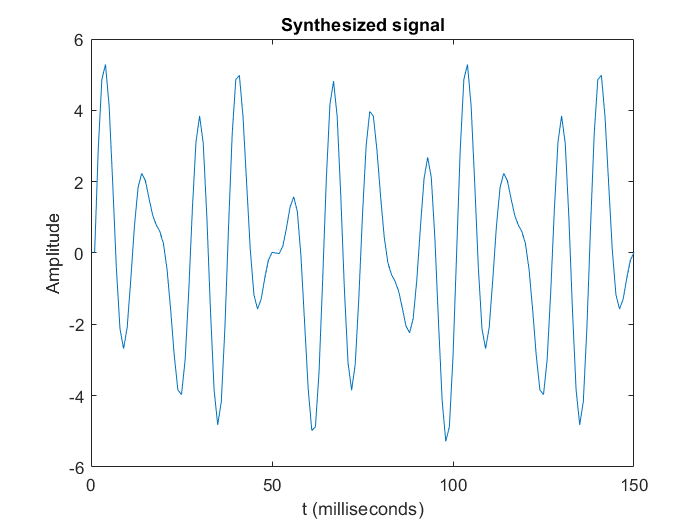

SS = x1+x2+x3;        % Generation of the synthesized signal
figure
plot(SS(1:150))        % Plot the figure
title('Synthesized signal')
xlabel('t (milliseconds)')
ylabel('Amplitude')

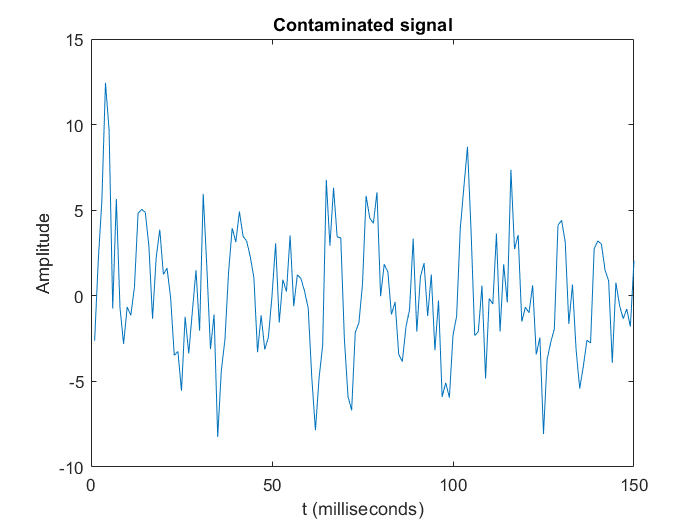

X = SS + 2*randn(size(t));  % Noisy signal added to synthesized signal 
plot(X(1:150))
title('Contaminated signal')
xlabel('t (milliseconds)')
ylabel('Amplitude')

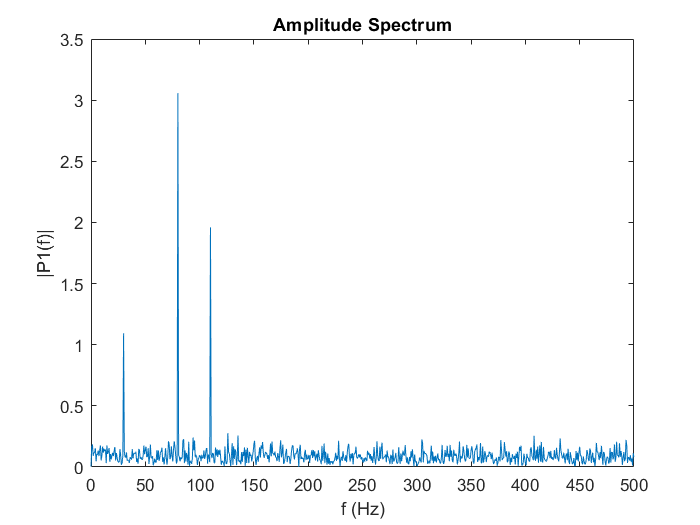

PS = fft(X);        % FFT of contaminated signal 
P2 = abs(PS/L);     % Abs of value PS
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);  % Spectrum P1 based on 
                              % P2 and the even-valued signal length L.

f = Fs*(0:(L/2))/L;    % Vector with the unilateral part of the signal
plot(f,P1) 
title('Amplitude Spectrum')
xlabel('f (Hz)')
ylabel('|P1(f)|')

PS = fft(SS);            % FFT of synthesized signal "SS(t)"
P2 = abs(PS/L);          % Abs of value P2 based of the PS vector divided of the L
                         % Getting the abs of the vector, the coefficients value changes 
                         % Agree with the vector L
P1 = P2(1:L/2+1);
P1                       % The P1 value show how the coefficients have value of 0 without 

P1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000


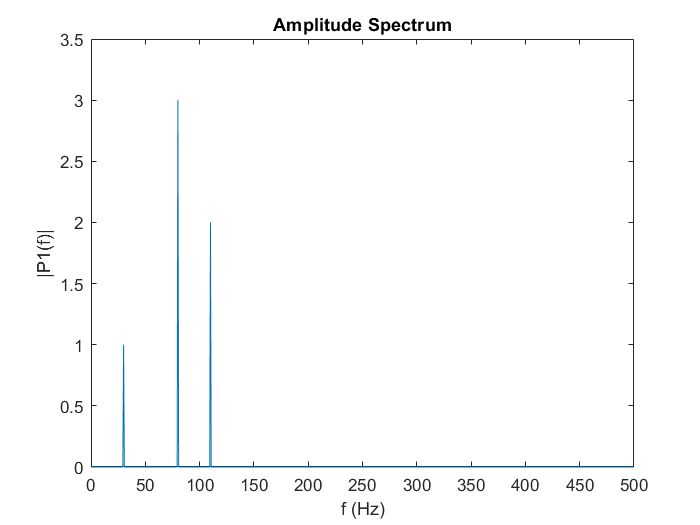

                         % considered the coefficients of the fundamental
                         % frequencies of 30, 80 and 110
                         
P1(2:end-1) = 2*P1(2:end-1);

plot(f,P1)              % Frequency spectrum without the noisy coeffiencients over to 200 Hz
title('Amplitude Spectrum')
xlabel('f (Hz)')
ylabel('|P1(f)|')

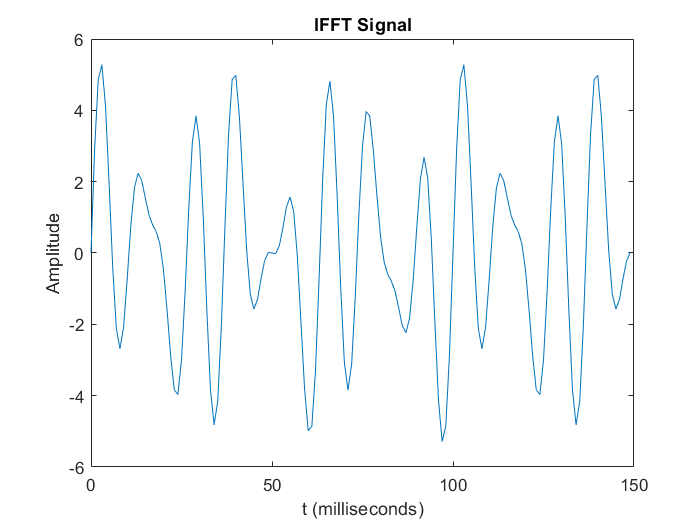

S2=ifft(PS, 1500);               % IFFT of the vector PS containing the values of FFT of X(t)
figure                          % with the number of samples recuperated to the synthesized signal
plot(1000*t(1:150),S2(1:150))    % The plot show the vector IFFT in the 
                             % same interval time of 1 to 150 ms 
                             % resembling the original synthesized signal                                
title('IFFT Signal')
xlabel('t (milliseconds)')
ylabel('Amplitude')

De acuerdo a la señal sintetizada por 3 señales senoidales obtenemos una señal con un espectro que asemeja el comportamiento conjunto de estas 3 señales con diferentes frecuencias y amplitudes que provoca una señal periodica. Al inducir una señal de ruido esta se ve contaminada modificando su forma, considerando esta señal incluso como no periodica, en la cual por observación no se pueden distinguir claramente las frecuencias fundamentales, ni las amplitudes de ella. 

Por lo tanto al querer observar los valores fundamnetales de la señal contaminada se realiza la FFT, en la cual pasamos la señal al dominio de la frecuencia, mostrando todas las señales contaminantes en el espectro, así como las frecuencias fundamentales de la señal sintetizada, permitiendo observar que dentro de la señal se enceuntran 3 frecuencias importantes, de 30, 80 y 110 Hz, con sus respectivas amplitudes. Para recuperar dicha señal y mostrar que a pesar de estar contaminada posee dichas caracteristicas podemos cambiar de dominio nuevamente aplicando la IFFT para regresar a visualizar los valores de las señales en el dominio del tiempo y ver como se comporta la señal sintetizada. 

Observando como la señal original y la señal reconstruida a partir de la IFFT se vuelve a mostrar periodica, con la misma forma de onda, misma frecuencia y misma amplitud. Siendo este el resultado esperado a la señal de la salida, al muestrear datos de forma "continua" siendo la señal sintetizada usada, teniendo el mismo resultado la señal de entrada a la señal contituida. Siendo el cambio de dominios una forma de poder manipular una señal contaminada obteniendo su información, y procesandola con el mismo número de muestreos para poder reconstruirla con la transformada inversa de la función. 